# Problema n°4

## Consigna

Determine los coeficientes de Fourier de la siguiente función descripta por:


$$P\left(t\right)=\frac{4}{T_p }*t-1$$
                      
$$\left(0\le t\le \frac{T_p }{2}\right)$$



$$P\left(t\right)=1-\frac{4}{T_p }*\left(t-\frac{T_p }{2}\right)$$
        
$$\left(\frac{T_p }{2}\le t\le T_p \right)$$


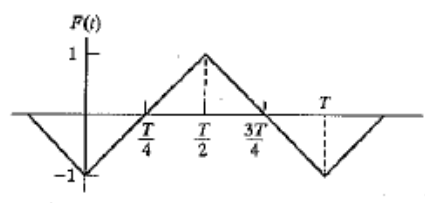

Determine la respuesta permanente de un sistema de un grado de libertad a una fuerza triangular como la indicada. El sistema se caracteriza por:


$$m=100\;\textrm{kg}$$
    
$$\varsigma =0\ldotp 1$$
    
$$k=1000\;\frac{N}{m}$$


La carga es:


$$\textrm{Po}=1N$$
    
$$T_p =2\pi \;s$$


## Respuesta para comparar

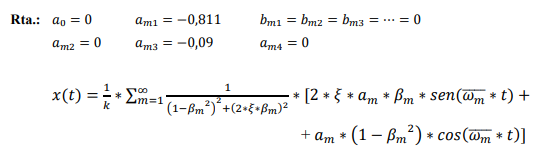

clc; clear;

%-----------------------FUNCIÓN DE CARGA EXTERNA---------------------------------

Tp = 2*pi;      %periodo de fuerza externa
wp = 2*pi/Tp;    %frecuencia angular de fuerza externa
Po = 1;         %amplitud de fuerza externa
dt = 0.0001;      %diferencial tiempo

t = 0:dt:Tp;    %vector tiempo. Este tiempo es el correspondiente a un periodo. Se usa para calcular an y bn
tg = 0:dt:10;   %Este es el vector tiempo que usaré para graficar. Puede tener la longitud que yo quiera.

Pt = zeros(1,length(t)); %vector que almacena la función P(t) en un solo periodo. Es para calcular an y bn
for i=1:length(t)
    t_mod = mod(t(i),Tp); %llevo cualquier valor de t a un rango entre 0 y Tp para poder meterlo en la siguiente funcion
    Pt(i) = (t_mod>=0).*(t_mod<=Tp/2).*(4/Tp*t_mod-1) + (t_mod>Tp/2).*(t_mod<Tp).*(1-4/Tp*(t_mod-Tp/2));
end

Pt_g = zeros(1,length(tg)); %vector que almacena la función P(t) en todo el tiempo que yo quiera graficar (usando tg)
for i=1:length(tg)
    t_mod = mod(tg(i),Tp); %llevo cualquier valor de t a un rango entre 0 y Tp para poder meterlo en la siguiente funcion
    Pt_g(i) = (t_mod>=0).*(t_mod<=Tp/2).*(4/Tp*t_mod-1) + (t_mod>Tp/2).*(t_mod<Tp).*(1-4/Tp*(t_mod-Tp/2));
end

subplot(2,2,1)
plot(tg,Pt_g)
title("Función P(t) original")
grid on
xlabel("t [s]")
ylabel("P(t) [N]")

%--------------------CARGA EXTERNA CON FOURIER----------------------------------

n = 4; %cantidad de armónicos a considerar

a0 = 2/Tp*trapz(t,Pt) %Componente a0

a0 = 2.7153e-05


A=zeros(length(t),n);   %P(t)*cos(n*wp*t)
B=zeros(length(t),n);   %P(t)*sin(n*wp*t)
an=zeros(n,1);
bn=zeros(n,1);

%Calculo los an y bn
for j=1:n
    A(:,j)= Pt.*cos(j*wp*t);
    an(j) = 2/Tp*trapz(t,A(:,j));

    B(:,j)= Pt.*sin(j*wp*t);
    bn(j) = 2/Tp*trapz(t,B(:,j));
end
an

an =    -0.8105
    0.0000
   -0.0900
    0.0000


bn

bn = 1.0e-08 *

   -0.1158
   -0.2316
   -0.3474
   -0.4633


a0

a0 = 2.7153e-05

P_fourier = zeros(1,length(tg)); %Vector que representa la serie de fourier para cada tiempo t
for i=1:length(P_fourier)
    P_fourier(i) = a0/2; %A cada término en el tiempo le sumo el coeficiente estático
end

armonicos = zeros(n,length(tg));

subplot(2,2,2)
for j=1:n
    armonicos(j,:) = an(j).*cos(j*wp*tg) + bn(j).*sin(j*wp*tg);
    plot(tg,armonicos(j,:));
    hold on
    P_fourier=P_fourier + armonicos(j,:);
end
armonicos

armonicos =    -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105   -0.8105
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

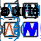

title("Armónicos")
hold off

subplot(2,2,3)
plot(tg,Pt_g)
hold on
plot(tg,P_fourier)
hold off
grid on
title("Serie de Fourier vs P(t)")

%------------------RESPUESTA EN EL TIEMPO------------------------------

m = 100;        %masa del sistema
k = 1000;       %Coeficiente de rigidez
w = sqrt(k/m);  %frecuencia natural
zitta = 0.1;    %relación de amortiguamiento crítico
betta = wp/w;   %relación de frecuencias
wd = 1;         %frecuencia natural circular amortiguada

phi=zeros(n,1); %vector que almacena los ángulos de desfasaje
D=zeros(n,1);   %Vector que almacena los D

for j=1:n
    phi(j)=atan(2*zitta*j*betta/(1-j^2*betta^2));
    D(j)=1/sqrt((1-j^2*betta^2)^2+(2*zitta*j*betta)^2);
end

xt = zeros(1,length(tg));    %Vector que almacena la respuesta en del sistema para cada tiempo t

%Para cada t, primero le sumo el término independiente
xt(1,:) = a0/(2*k);

%Ahora a cada t le sumo los términos que dependen de n
for j=1:n
    xt= xt + an(j)/k * D(j) .* cos(j*wp*tg-phi(j)) + bn(j)/k * D(j) .* sin(j*wp*tg-phi(j));
end

%% ----------------GRAFICAS--------------------------


subplot(2,2,4)
[ax, h1, h2] = plotyy(tg, xt, tg, P_fourier);
set(h1, 'LineWidth', 2, 'Color', 'r');
ylabel(ax(1), 'X(t)');

set(h2, 'LineWidth', 2, 'Color', 'b');
set(ax(2), 'YColor', 'b');
ylabel(ax(2), 'P(t) Fourier');
title("Respuesta x(t) vs P-fourier");
grid on